year = 2002

baseDir = fullfile('E:', 'University', 'EngSci Thesis', 'Thesis work');
dataDir = fullfile(baseDir, 'results','daily_area');
figureDir = fullfile(baseDir, 'figures', 'yearly_plot');

all_area = [];
all_dates = [];

for m = 1:12
    path_m = fullfile(dataDir, num2str(year), sprintf('daily_area_m%02u_y%u.mat', m, year));
    if isfile(path_m)
        S = load(path_m, 'areas', 'digital_date_ts');
        all_area = [all_area, S.areas];
        all_dates = [all_dates, S.digital_date_ts];
    else
        error_string = sprintf('File "daily_area_m%02u_y%u.mat" is missing', m, year);
        disp(error_string);
    end
end

% Plot all_area against all_dates
plot(all_dates, all_area, 'Color', [0 0 1], 'LineWidth', 1);
title(sprintf('Year long area variation of Scoresby Sund Polynya (%u)', year));
xlabel('Date');
ylabel('Area (km^2)')
is_firstday = day(all_dates)==1;
xticks(all_dates(is_firstday));
xticklabels(datestr(all_dates(is_firstday), 'mmm dd')); % "Jan 01", etc.

month = 1;
all_max_areas = [];
all_max_areas_digital_date = [];
month_string = {'January', 'February', 'March', 'April', 'May', 'June', 'July', 'August', 'September', 'October', 'November', 'December'};

base_dir = fullfile('E:', 'University', 'EngSci Thesis', 'Thesis work');
input_data_dir = fullfile(base_dir, 'results', 'daily_area');

for year = 2002:2025
    dataset_string = fullfile(input_data_dir , num2str(year), sprintf('daily_area_m%02u_y%u.mat', month, year));
    if isfile(dataset_string)
        load(dataset_string, 'areas', 'digital_date_ts');

        [max_area, max_area_index] = max(areas);
        max_area_date = digital_date_ts(max_area_index);

        all_max_areas = [all_max_areas max_area];
        all_max_areas_digital_date = [all_max_areas_digital_date, max_area_date];
    
    else
        fprintf('Data file not found:\n  %s\n', dataset_string);
    end

end

clear year; % clear the variable 'year' to use the datetime function 'year'

fig = figure('Visible','off');
plot(year(all_max_areas_digital_date), all_max_areas);
xlabel('Year');
ylabel('Area (km^2)');
title_string = sprintf('Evolution of maximum polynya area in %s from 2022 to 2025', month_string{month});
title(title_string);

% Save data
output_data_dir = fullfile(base_dir, 'results','all_max_areas');
if ~exist(output_data_dir, 'dir')
    mkdir(output_data_dir);
end
output_file_name = fullfile(output_data_dir, sprintf('max_areas_in_m%02u.mat', month));
save(output_file_name, 'all_max_areas', 'all_max_areas_digital_date');

% Save figure
output_fig_dir = fullfile(base_dir, 'figures','evolution_of_month_max');
figFilename = fullfile(output_fig_dir, sprintf('evolution_of_month_max_m%02u.png', month));
exportgraphics(fig, figFilename, 'Resolution', 300);
close(fig);

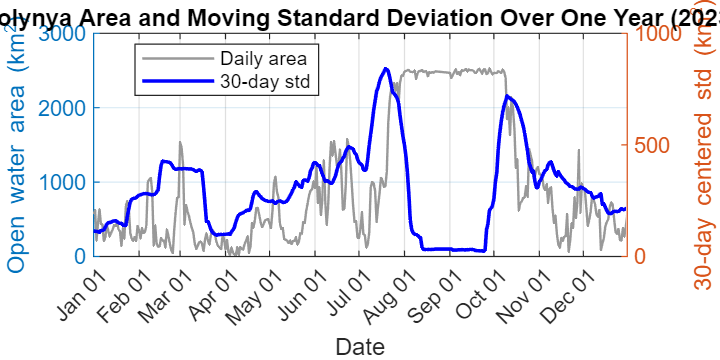

targetYear=2023;
windowSize = 30;   % centered window (in days)

baseDir = fullfile('E:', 'University', 'EngSci Thesis', 'Thesis work');
dataDir = fullfile(baseDir, 'results','daily_area');
figureDir = fullfile(baseDir, 'figures', 'moving_std');

% --- Load Dec (prev), 12 months (current), Jan (next) ---
all_area = [];
all_dates = [];

% Previous December
if targetYear > 0
    dec_path = fullfile(dataDir, num2str(targetYear-1), sprintf('daily_area_m12_y%u.mat', targetYear-1));
    if isfile(dec_path)
        S = load(dec_path, 'areas', 'digital_date_ts');
        all_area = [S.areas, all_area];
        all_dates = [S.digital_date_ts, all_dates];
    else
        disp(sprintf('%s file not loaded.\n', dec_path));
    end
end

% Current targetYear months (whatever months available)
for m = 1:12
    path_m = fullfile(dataDir, num2str(targetYear), sprintf('daily_area_m%02u_y%u.mat', m, targetYear));
    if isfile(path_m)
        S = load(path_m, 'areas', 'digital_date_ts');
        all_area = [all_area, S.areas];
        all_dates = [all_dates, S.digital_date_ts];
    else
        disp(sprintf('%s file not loaded.\n', path_m));
    end
end

% Following January
jan_path = fullfile(dataDir, num2str(targetYear+1), sprintf('daily_area_m01_y%u.mat', targetYear+1));
if isfile(jan_path)
    S = load(jan_path, 'areas', 'digital_date_ts');
    all_area = [all_area, S.areas];
    all_dates = [all_dates, S.digital_date_ts];
else
    disp(sprintf('%s file not loaded.\n', jan_path));
end

% --- Compute centered moving std ---
mov_std = movstd(all_area, windowSize, 'omitnan');

% --- Extract main targetYear (discard prev/next targetYear dates used for continuity) ---
inYear = year(all_dates) == targetYear;
mov_std = mov_std(inYear);
all_area = all_area(inYear);
all_dates = all_dates(inYear);

% --- Plotting ---
%fig = figure('Visible','off', 'Units','normalized', 'Position',[0.2 0.2 0.5 0.4]);
fig = figure('Units','normalized', 'Position',[0.2 0.2 0.5 0.4]);

yyaxis left
plot(all_dates, all_area, 'Color', [0.6 0.6 0.6], 'LineWidth', 1);
ylabel('Open water area (km^2)');

yyaxis right
plot(all_dates, mov_std, 'b', 'LineWidth', 1.5);
ylabel(sprintf('%d-day centered std (km^2)', windowSize));

title(sprintf('Polynya Area and Moving Standard Deviation Over One Year (%u)', targetYear));
xlabel('Date');
grid on;

% Format x-axis: show first day of each month
is_firstday = day(all_dates)==1;
xticks(all_dates(is_firstday));
xticklabels(datestr(all_dates(is_firstday), 'mmm dd')); % "Jan 01", etc.
xlim([all_dates(1), all_dates(end)]);
legend({'Daily area','30-day std'}, 'Location', 'best');

% Plot the average of each month's maximum
baseDir = fullfile('E:', 'University', 'EngSci Thesis', 'Thesis work');
dataDir = fullfile(baseDir, 'results','all_max_areas');
figureDir = fullfile(baseDir, 'figures', 'average_max');

monthly_mean = zeros(1, 12);
month_string = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};

for month = 1:12
    % Load data
    data_file_string = fullfile(dataDir, sprintf('max_areas_in_m%02u.mat', month))
    S = load(data_file_string);
    
    % Take average
    M = mean(S.all_max_areas);
    monthly_mean(month) = M;
end        

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m01.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m02.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m03.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m04.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m05.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m06.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m07.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m08.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m09.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m10.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m11.mat'

data_file_string = 'E:\University\EngSci Thesis\Thesis work\results\all_max_areas\max_areas_in_m12.mat'

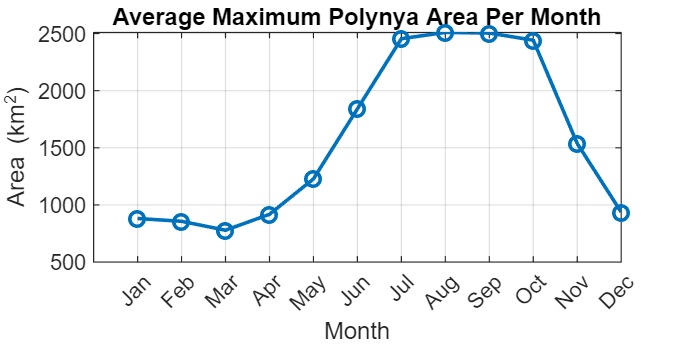


% Plot

%fig = figure('Visible','off', 'Units','normalized', 'Position',[0.2 0.2 0.5 0.4]);
fig = figure('Units','normalized', 'Position',[0.2 0.2 0.5 0.4]);

plot(1:12, monthly_mean, '-o', 'LineWidth', 1.5);
xlabel('Month');
ylabel('Area (km^2)');
grid on;
title('Average Maximum Polynya Area Per Month');
xticks(1:12)
xticklabels(month_string);